%% Example: d^2c/dt^2 + 9 dc/dt + 9c(t) = 9r(t)


%% Symbolic work (partfrac, ilaplace, laplace)


clear
clc

syms t s C R c(t) r(t)

%% 1. Define ODE
ode = diff(c, t, 2) - diff(c, t) + 2*c == 2*r;

%% 2. Take Laplace Transform
ODE_L = laplace(ode, t, s);

%% 3. Apply zero initial conditions
ODE_L = subs(ODE_L, ...
    {c(0), subs(diff(c(t), t), t, 0)}, ...
    {0, 0});

%% 4. Replace Laplace terms with C(s), R(s)
ODE_L = subs(ODE_L, laplace(c(t), t, s), C);
ODE_L = subs(ODE_L, laplace(r(t), t, s), R);

%% 5. Solve for transfer function G(s) = C(s)/R(s)
G = simplify(solve(ODE_L, C) / R);

disp('Transfer Function G(s) = C(s)/R(s):')

Transfer Function G(s) = C(s)/R(s):


pretty(G)

     2
----------
 2
s  - s + 2




% Factor the denominator
% Factor the denominator of G
[numG, denG] = numden(G);        % symbolic numerator and denominator
denG_factored = factor(denG);    % factor denominator
disp('Factored Denominator of G(s):')

Factored Denominator of G(s):


pretty(denG_factored)

 2
s  - s + 2



% Substitute the factored denominator back into G
G = simplify(numG / denG_factored);
disp('G(s) with factored denominator substituted in:')

G(s) with factored denominator substituted in:


pretty(G)

     2
----------
 2
s  - s + 2



% Also display roots (poles) numerically
poles = double(solve(denG == 0, s))

poles =    0.5000 - 1.3229i
   0.5000 + 1.3229i


disp('Poles (roots of denominator):')

Poles (roots of denominator):


disp(poles)

   0.5000 - 1.3229i
   0.5000 + 1.3229i



% 5.a Write the denominator of G in terms of its factored poles
% Extract denominator (already have denG_factored). If denG_factored is a product,
% ensure it's displayed as product of (s - pole).
% Get numeric poles (if symbolic factor gave irreducible quadratic, use roots)
if isempty(denG_factored)
    denG_sym = denG;
else
    denG_sym = denG_factored;
end

% Try to express denominator as product of linear factors (s - p1)*(s - p2)...
p_sym = solve(denG == 0, s);           % symbolic poles
p_sym = unique(p_sym);                 % remove duplicates if any

% Build factored form from symbolic poles
if ~isempty(p_sym)
    denom_factored_from_poles = prod(s - p_sym)
    disp('Denominator written as product of (s - pole) factors (symbolic):')
    pretty(factor(prod(s - p_sym)))    % display factored form
else
    disp('Could not determine symbolic poles to form factored denominator.')
end

$$denom\_factored\_from\_poles = -\left(s-\frac{1}{2}+\frac{\sqrt{7}\,\mathrm{i}}{2}\right)\,\left(\frac{1}{2}-s+\frac{\sqrt{7}\,\mathrm{i}}{2}\right)$$

Denominator written as product of (s - pole) factors (symbolic):


/     sqrt(7) 1i   1      sqrt(7) 1i   1 \
| s + ---------- - -, s - ---------- - - |
\          2       2           2       2 /




G = numG / denom_factored_from_poles 

$$G = -\frac{2}{\left(s-\frac{1}{2}+\frac{\sqrt{7}\,\mathrm{i}}{2}\right)\,\left(\frac{1}{2}-s+\frac{\sqrt{7}\,\mathrm{i}}{2}\right)}$$



%% 6. Partial Fraction Expansion (decimal poles)
G_pf = partfrac(G, s)

$$G\_pf = \frac{4\,\sqrt{7}\,\mathrm{i}}{7\,\left(1-2\,s+\sqrt{7}\,\mathrm{i}\right)}+\frac{4\,\sqrt{7}\,\mathrm{i}}{7\,\left(2\,s-1+\sqrt{7}\,\mathrm{i}\right)}$$


disp('Partial Fraction Form (VERIFY COEFFICIENT OF S:')

Partial Fraction Form (VERIFY COEFFICIENT OF S:


pretty(G_pf)

       sqrt(7) 4i                 sqrt(7) 4i
------------------------ + ------------------------
7 (1 + sqrt(7) 1i - 2 s)   7 (2 s + sqrt(7) 1i - 1)




%% 7. Time-domain response (impulse response)
g_t = ilaplace(G, s, t);

disp('Time Domain Response g(t):')

Time Domain Response g(t):


pretty(g_t)

           /   t (- 1 + sqrt(7) 1i) \                 / t (1 + sqrt(7) 1i) \
sqrt(7) exp| - -------------------- | 2i   sqrt(7) exp| ------------------ | 2i
           \             2          /                 \          2         /
---------------------------------------- - ------------------------------------
                    7                                        7






%% Control toolbox work (step, bode, pole)
s_tf = tf('s');            % use a different variable name
sys = 1/(s_tf^2 + 9*s_tf + 9);
pole(sys)

ans =    -7.8541
   -1.1459


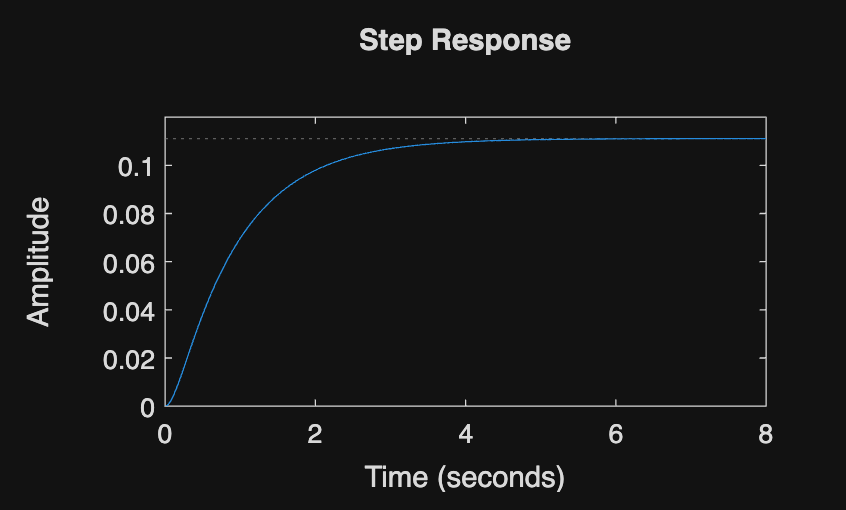

step(sys)




%% ============================================================
%  RC Circuit: Time Domain → Laplace → Transfer Function
%  ODE: RC*c'(t) + c(t) = r(t)
%% ============================================================

%% STEP 1: Define symbolic variables
syms t s
syms c(t) r(t)
R = 1000;   % resistance in ohms (constant)
C = 1e-3;   % capacitance in farads (constant)

%% STEP 2: Define the ODE in time domain
ode = R*C*diff(c,t) + c(t) == r(t)

$$ode(t) = \frac{\partial }{\partial t}c\left(t\right)+c\left(t\right)=r\left(t\right)$$

% RC*c'(t) + c(t) = r(t)

%% STEP 3: Take Laplace transform (zero initial conditions assumed)
ode_laplace = laplace(ode, t, s)

$$ode\_laplace = s\,\mathrm{laplace}\left(c\left(t\right),t,s\right)-c\left(0\right)+\mathrm{laplace}\left(c\left(t\right),t,s\right)=\mathrm{laplace}\left(r\left(t\right),t,s\right)$$

% Result: RC*s*C(s) + C(s) = R(s)

%% STEP 4: Solve for transfer function H(s) = C(s)/R(s)
syms Cs Rs
Hs = 1 / (R*C*s + 1)

$$Hs = \frac{1}{s+1}$$

% Result: H(s) = 1 / (RCs + 1)

%% ============================================================
%  STEP 5: Build transfer function using Control Toolbox
%% ============================================================
s_tf = tf('s');
G = 1 / (R*C*s_tf + 1)


G =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



%% STEP 6: Inspect the system
disp('--- Poles ---')

--- Poles ---


pole(G)

ans = -1

% Pole at s = -1/(RC) → negative = stable

disp('--- Zero initial condition step response ---')

--- Zero initial condition step response ---


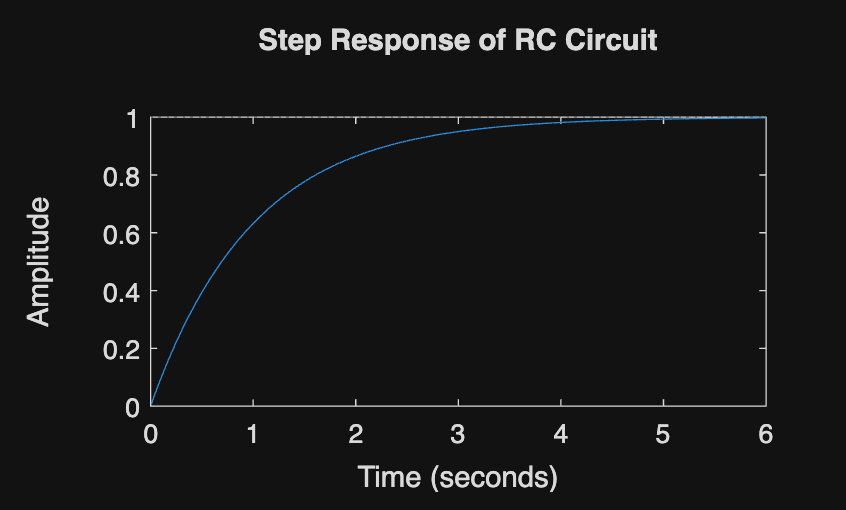

figure; step(G); title('Step Response of RC Circuit')


disp('--- Bode Plot ---')

--- Bode Plot ---


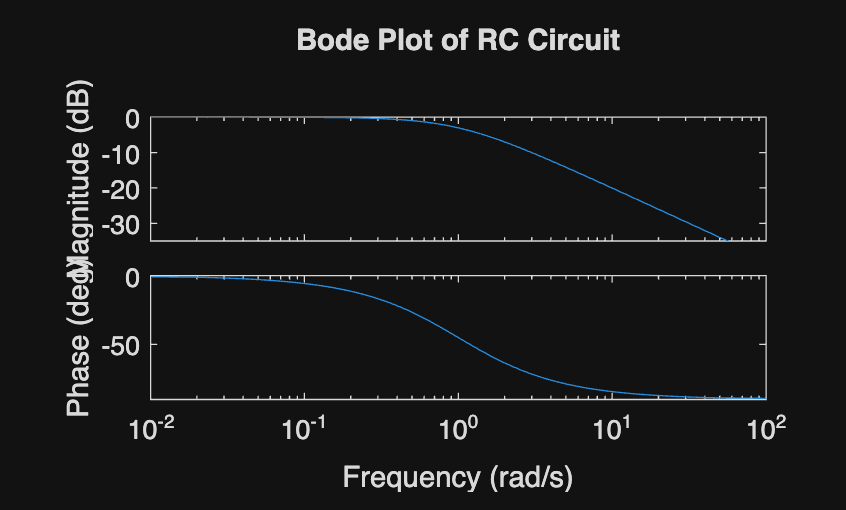

figure; bode(G); title('Bode Plot of RC Circuit')